# Exercise 6: Multiphase flow

## Spezi colours

sblau = [56 58 107] / 255; smag  = [203 31 115] / 255;  
srot  = [224 58 60] / 255; soran = [242, 136, 1] / 255;
lwidth = 2;

## Probe Pressures

### Read data

%sim_p = readtable("../postProcessing/probes1/0/p_rgh");
sim_p = readtable("./team/fine_probes_p.csv");
sim_p = sim_p(2:end, :);

val_p = readtable("exp_data.txt");

sim_p.Properties.Vaval_p = readtable("exp_data.txt");riableNames

ans = 1×9 cell array
    {'time'}    {'P1'}    {'P2'}    {'P3'}    {'P4'}    {'P5'}    {'P6'}    {'P7'}    {'P8'}


val_p.Properties.VariableNames

ans = 1×9 cell array
    {'Time_s_'}    {'P1_Pa_'}    {'P2_Pa_'}    {'P3_Pa_'}    {'P4_Pa_'}    {'P5_Pa_'}    {'P6_Pa_'}    {'P7_Pa_'}    {'P8_Pa_'}


### Plot probe 1

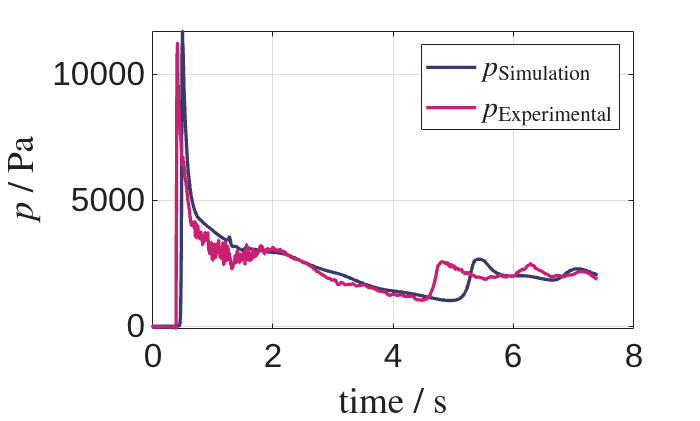

figure
plot(sim_p.time, sim_p.P1, 'LineWidth', lwidth, 'Color', sblau)
hold on
plot(val_p.Time_s_, val_p.P1_Pa_, 'LineWidth', lwidth, 'Color', smag)
hold off, grid on
xlabel('time / s', 'Interpreter', 'latex')
ylabel('$p$ / Pa', 'Interpreter', 'latex'),
legend('$p_\mathrm{Simulation}$', '$p_\mathrm{Experimental}$', 'Interpreter', 'latex');
set(gca, 'FontSize', 20)

### Plot Probe 1-8

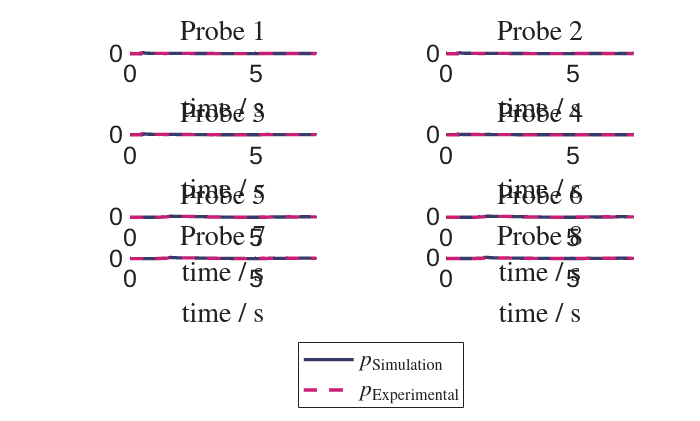

figure
tiledlayout(4,2)
for i = 2:9
    nexttile
    col_name_sim = sim_p.Properties.VariableNames{i};
    col_name_val = val_p.Properties.VariableNames{i};


    plot(sim_p.time, sim_p.(col_name_sim), 'LineWidth', lwidth, 'Color', sblau)
    hold on
    plot(val_p.Time_s_, val_p.(col_name_val), '--', 'LineWidth', lwidth, 'Color', smag)
    hold off
    
    title(sprintf('Probe %d',i-1), 'Interpreter', 'latex')
    xlabel('time / s', 'Interpreter', 'latex')
    ylabel('$p$ / Pa', 'Interpreter', 'latex')
    grid on
    set(gca, 'FontSize', 15)
end

lgd = legend('$p_\mathrm{Simulation}$', '$p_\mathrm{Experimental}$', 'Interpreter', 'latex');
lgd.Layout.Tile= "south";

## Water volume

Soll: 0.6754

### Read data

sim_w_c = readtable("coarseMesh/volFieldValue.dat");

sim_w_f = readtable("fineMesh/volFieldValue.dat");

sim_w_c.Properties.VariableNames

ans = 1×2 cell array
    {'x_Time'}    {'volIntegrate_alpha_water_'}


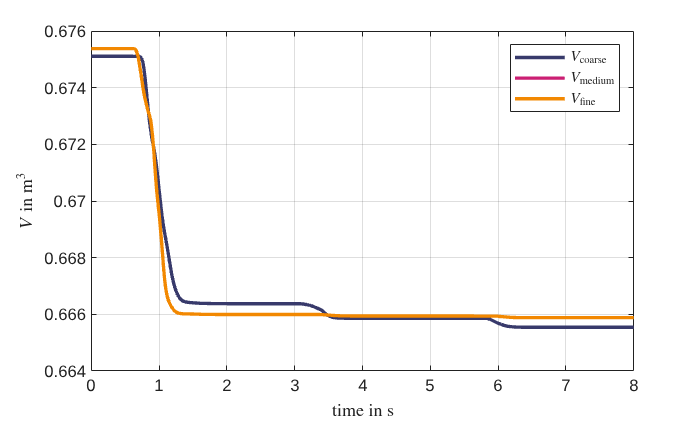

figure
plot(sim_w_c.x_Time, sim_w_c.volIntegrate_alpha_water_, 'LineWidth', lwidth, 'Color', sblau)
grid on, hold on
plot(sim_w_f.x_Time, sim_w_f.volIntegrate_alpha_water_, 'LineWidth', lwidth, 'Color', smag)
plot(sim_w_f.x_Time, sim_w_f.volIntegrate_alpha_water_, 'LineWidth', lwidth, 'Color', soran)
hold off
xlabel('time in s', 'Interpreter', 'latex')
ylabel('$V$ in $\mathrm{m}^3$', 'Interpreter', 'latex')
legend('$V_\mathrm{coarse}$', '$V_\mathrm{medium}$', '$V_\mathrm{fine}$', 'Interpreter', 'latex');